# Tutorial 5:   Reaction information and rates

## Topics:

##       - stoichiometric coefficients

##       - reaction rates of progress

##       - species production rates

##       - reaction equations

##       - equilibrium constants

##       - rate multipliers

### Setting Up The Gas Object

----------------------------------------------

LoadCantera;

Cantera is ready for use


g = GRI30('None')


  gri30:

       temperature   300 K
          pressure   1.0133e+05 Pa
           density   0.081894 kg/m^3
  mean mol. weight   2.016 kg/kmol
   phase of matter   gas

                          1 kg             1 kmol     
                     ---------------   ---------------
          enthalpy             26469             53361  J
   internal energy       -1.2108e+06        -2.441e+06  J
           entropy             64910        1.3086e+05  J/K
    Gibbs function       -1.9447e+07       -3.9204e+07  J
 heat capacity c_p             14311             28851  J/K
 heat capacity c_v             10187             20536  J/K

                      mass frac. Y      mole frac. X     chem. pot. / RT
                     ---------------   ---------------   ---------------
                H2                 1                 1           -15.717
                 H                 0                 0  
                 O                 0                 0  
                O2             

g.TPX = {1500, oneatm, ones(g.nSpecies,1)}


  gri30:

       temperature   1500 K
          pressure   1.0132e+05 Pa
           density   0.23459 kg/m^3
  mean mol. weight   28.875 kg/kmol
   phase of matter   gas

                          1 kg             1 kmol     
                     ---------------   ---------------
          enthalpy        6.1817e+06         1.785e+08  J
   internal energy        5.7498e+06        1.6603e+08  J
           entropy             11504        3.3218e+05  J/K
    Gibbs function       -1.1074e+07       -3.1977e+08  J
 heat capacity c_p              2378             68665  J/K
 heat capacity c_v              2090             60351  J/K

                      mass frac. Y      mole frac. X     chem. pot. / RT
                     ---------------   ---------------   ---------------
                H2         0.0013173          0.018868           -22.572
                 H        0.00065866          0.018868           -2.3242
                 O          0.010454          0.018868           -5.446

### Kinetics Methods

------------------------------

Methods are provided that compute many quantities of interest for kinetics. Some of these are:

#### 1) Stoichiometric coefficients

nu_r   = g.stoichReactant    % reactant stoichiometric coefficient mstix

nu_r =    (3,1)        2
   (2,2)        1
   (3,2)        1
   (1,3)        1
   (3,3)        1
   (3,4)        1
   (7,4)        1
   (3,5)        1
   (8,5)        1
   (3,6)        1
  (10,6)        1
   (3,7)        1
  (11,7)        1
   (3,8)        1
  (12,8)        1
   (3,9)        1
  (12,9)        1
   (3,10)       1
  (13,10)       1
   (3,11)       1
  (14,11)       1
   (3,12)       1
  (15,12)       1
   (3,13)       1
  (17,13)       1
   (3,14)       1
  (17,14)       1
   (3,15)       1
  (18,15)       1
   (3,16)       1
  (19,16)       1
   (3,17)       1
  (20,17)       1
   (3,18)       1
  (21,18)       1
   (3,19)       1
  (21,19)       1
   (3,20)       1
  (22,20)       1
   (3,21)       1
  (23,21)       1
   (3,22)       1
  (23,22)       1
   (3,23)       1
  (23,23)       1
   (3,24)       1
  (24,24)       1
   (3,25)       1
  (25,25)       1
   (3,26)       1
  (26,26)       1
   (3,27)       1
  (27,27)       1
   (3,28)       1
  (28,28)       1
   

nu_p   = g.stoichProduct    % product stoichiometric coefficient mstix

nu_p =    (4,1)        1
   (5,2)        1
   (2,3)        1
   (5,3)        1
   (4,4)        1
   (5,4)        1
   (5,5)        1
   (7,5)        1
   (2,6)        1
  (15,6)        1
   (2,7)        1
  (17,7)        1
   (1,8)        1
  (15,8)        1
   (2,9)        1
  (17,9)        1
   (2,10)       1
  (18,10)       1
   (5,11)       1
  (13,11)       1
  (16,12)       1
   (5,13)       1
  (15,13)       1
   (2,14)       1
  (16,14)       1
   (5,15)       1
  (17,15)       1
   (5,16)       1
  (18,16)       1
   (5,17)       1
  (18,17)       1
   (5,18)       1
  (19,18)       1
   (5,19)       1
  (20,19)       1
  (10,20)       1
  (15,20)       1
   (2,21)       1
  (28,21)       1
   (5,22)       1
  (22,22)       1
  (11,23)       1
  (15,23)       1
   (2,24)       1
  (29,24)       1
  (13,25)       1
  (17,25)       1
  (13,26)       1
  (18,26)       1
   (5,27)       1
  (26,27)       1
   (2,28)       1
  (15,28)       2
   (5,29)       1
  (28,29)       1
  (

nu_net = g.stoichNet  % net (product - reactant) stoichiometric

nu_net =    (3,1)       -2
   (4,1)        1
   (2,2)       -1
   (3,2)       -1
   (5,2)        1
   (1,3)       -1
   (2,3)        1
   (3,3)       -1
   (5,3)        1
   (3,4)       -1
   (4,4)        1
   (5,4)        1
   (7,4)       -1
   (3,5)       -1
   (5,5)        1
   (7,5)        1
   (8,5)       -1
   (2,6)        1
   (3,6)       -1
  (10,6)       -1
  (15,6)        1
   (2,7)        1
   (3,7)       -1
  (11,7)       -1
  (17,7)        1
   (1,8)        1
   (3,8)       -1
  (12,8)       -1
  (15,8)        1
   (2,9)        1
   (3,9)       -1
  (12,9)       -1
  (17,9)        1
   (2,10)       1
   (3,10)      -1
  (13,10)      -1
  (18,10)       1
   (3,11)      -1
   (5,11)       1
  (13,11)       1
  (14,11)      -1
   (3,12)      -1
  (15,12)      -1
  (16,12)       1
   (3,13)      -1
   (5,13)       1
  (15,13)       1
  (17,13)      -1
   (2,14)       1
   (3,14)      -1
  (16,14)       1
  (17,14)      -1
   (3,15)      -1
   (5,15)       1
  (17,15)       1
 

For any of these, the (k,i) matrix element is the stoichiometric coefficient of species k in reaction i. Since these coefficient matrices are very sparse, they are implemented as MATLAB sparse matrices.

#### 2) Reaction rates of progress

Methods rop_f, rop_r, and rop_net return column vectors containing the forward, reverse, and net (forward - reverse) rates of progress, respectively, for all reactions.

qf = g.ropForward';
qr = g.ropReverse';
qn = g.ropNet';
rop = [qf, qr, qn]

rop =    2.1606e-02   1.8818e-11   2.1606e-02
   7.5883e-02   1.0807e-09   7.5883e-02
   4.1891e+01   3.6308e+01   5.5835e+00
   4.6996e+02   1.0348e-05   4.6996e+02
   1.3306e+02   1.5563e-01   1.3291e+02
   1.3394e+03   1.1223e-21   1.3394e+03
   1.8798e+03   6.5505e-10   1.8798e+03
   3.5247e+02   1.4426e-24   3.5247e+02
   3.5247e+02   2.8494e-12   3.5247e+02
   1.1890e+03   1.8327e-06   1.1890e+03


This plots the rates of progress

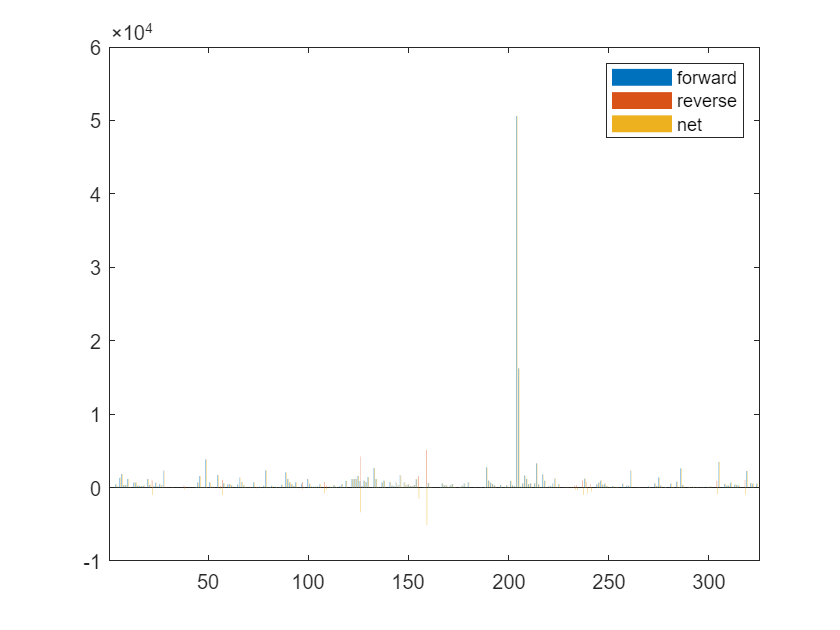

figure(1);
bar(rop);
legend('forward','reverse','net');

#### 3) Species production rates

Methods creationRates, destructionRates, and netProdRates return column vectors containing the creation, destruction, and net production (creation - destruction) rates, respectively, for all species.

cdot = g.creationRates';
ddot = g.destructionRates';
wdot = g.netProdRates';
rates = [cdot, ddot, wdot]

rates =    2.3026e+04   3.5105e+03   1.9516e+04
   1.1337e+05   4.3407e+04   6.9963e+04
   6.8311e+03   3.3684e+04  -2.6853e+04
   4.1259e+03   5.5471e+03  -1.4212e+03
   1.7846e+04   1.8069e+04  -2.2235e+02
   1.1296e+04   2.0180e+03   9.2780e+03
   3.1627e+03   6.0524e+03  -2.8897e+03
   1.9016e+02   2.4674e+03  -2.2772e+03
   4.6685e+03   5.7805e+03  -1.1120e+03
   6.9044e+03   1.7396e+04  -1.0492e+04


This plots the production rates

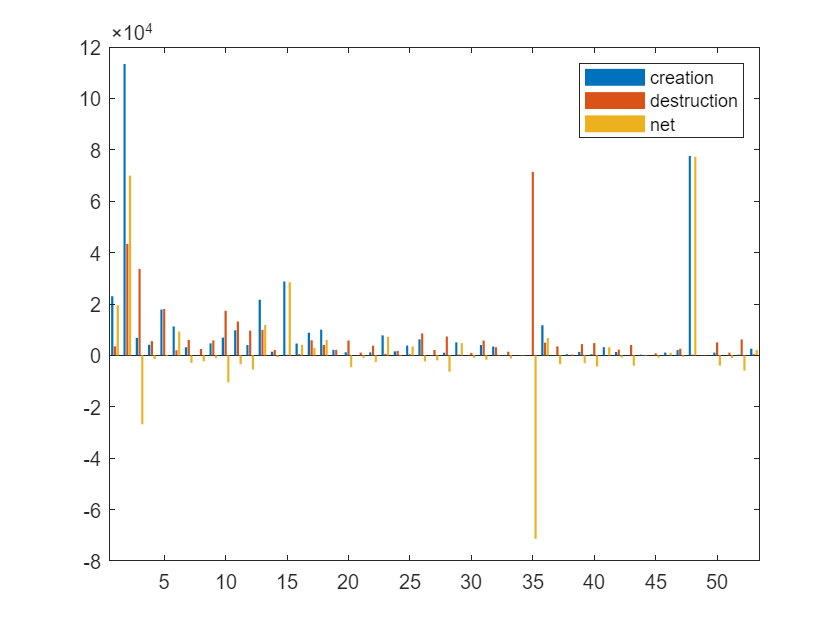

figure(2);
bar(rates);
legend('creation','destruction','net');

For comparison, the production rates may also be computed directly from the rates of progress and stoichiometric coefficients.

cdot2 = nu_p*qf + nu_r*qr;
creation = [cdot, cdot2, cdot - cdot2]

creation =    2.3026e+04   2.3026e+04            0
   1.1337e+05   1.1337e+05  -2.9104e-11
   6.8311e+03   6.8311e+03   9.0949e-13
   4.1259e+03   4.1259e+03            0
   1.7846e+04   1.7846e+04  -3.6380e-12
   1.1296e+04   1.1296e+04  -1.8190e-12
   3.1627e+03   3.1627e+03  -9.0949e-13
   1.9016e+02   1.9016e+02  -2.8422e-14
   4.6685e+03   4.6685e+03            0
   6.9044e+03   6.9044e+03  -9.0949e-13



ddot2 = nu_r*qf + nu_p*qr;
destruction = [ddot, ddot2, ddot - ddot2]

destruction =    3.5105e+03   3.5105e+03            0
   4.3407e+04   4.3407e+04  -1.4552e-11
   3.3684e+04   3.3684e+04            0
   5.5471e+03   5.5471e+03  -9.0949e-13
   1.8069e+04   1.8069e+04  -3.6380e-12
   2.0180e+03   2.0180e+03            0
   6.0524e+03   6.0524e+03            0
   2.4674e+03   2.4674e+03            0
   5.7805e+03   5.7805e+03            0
   1.7396e+04   1.7396e+04            0



wdot2 = nu_net * qn;
net = [wdot, wdot2, wdot - wdot2]

net =    1.9516e+04   1.9516e+04            0
   6.9963e+04   6.9963e+04   1.4552e-11
  -2.6853e+04  -2.6853e+04            0
  -1.4212e+03  -1.4212e+03  -2.2737e-13
  -2.2235e+02  -2.2235e+02  -2.2169e-12
   9.2780e+03   9.2780e+03  -3.6380e-12
  -2.8897e+03  -2.8897e+03   4.5475e-13
  -2.2772e+03  -2.2772e+03            0
  -1.1120e+03  -1.1120e+03            0
  -1.0492e+04  -1.0492e+04            0


#### 4) Reaction equations

e8    = g.reactionEqn(8)             % equation for reaction 8

e8 = 1×1 cell array
    {'CH2(S) + O <=> CO + H2'}


e1_10 = g.reactionEqn(1:10)          % equation for rxns 1 - 10

e1_10 = 10×1 cell array
    {'2 O + M <=> O2 + M'    }
    {'H + O + M <=> OH + M'  }
    {'H2 + O <=> H + OH'     }
    {'HO2 + O <=> O2 + OH'   }
    {'H2O2 + O <=> HO2 + OH' }
    {'CH + O <=> CO + H'     }
    {'CH2 + O <=> H + HCO'   }
    {'CH2(S) + O <=> CO + H2'}
    {'CH2(S) + O <=> H + HCO'}
    {'CH3 + O <=> CH2O + H'  }


eqs = g.reactionEqn               % all equations

eqs = 325×1 cell array
    {'2 O + M <=> O2 + M'      }
    {'H + O + M <=> OH + M'    }
    {'H2 + O <=> H + OH'       }
    {'HO2 + O <=> O2 + OH'     }
    {'H2O2 + O <=> HO2 + OH'   }
    {'CH + O <=> CO + H'       }
    {'CH2 + O <=> H + HCO'     }
    {'CH2(S) + O <=> CO + H2'  }
    {'CH2(S) + O <=> H + HCO'  }
    {'CH3 + O <=> CH2O + H'    }
    {'CH4 + O <=> CH3 + OH'    }
    {'CO + O (+M) <=> CO2 (+M)'}
    {'HCO + O <=> CO + OH'     }
    {'HCO + O <=> CO2 + H'     }
    {'CH2O + O <=> HCO + OH'   }
    {'CH2OH + O <=> CH2O + OH' }
    {'CH3O + O <=> CH2O + OH'  }
    {'CH3OH + O <=> CH2OH + OH'}
    {'CH3OH + O <=> CH3O + OH' }
    {'C2H + O <=> CH + CO'     }
    {'C2H2 + O <=> H + HCCO'   }
    {'C2H2 + O <=> C2H + OH'   }
    {'C2H2 + O <=> CH2 + CO'   }
    {'C2H3 + O <=> CH2CO + H'  }
    {'C2H4 + O <=> CH3 + HCO'  }
    {'C2H5 + O <=> CH2O + CH3' }
    {'C2H6 + O <=> C2H5 + OH'  }
    {'HCCO + O <=> 2 CO + H'   }
    {'CH2CO + O <=> HCCO + OH' }
    {'CH2CO + O <=> 

#### 5) Equilibrium constants

The equilibrium constants are computed in concentration units, with concentrations in kmol/m^3.

kc = g.Kc;
for i = 1:g.nReactions
   fprintf('%50s  %13.5g\n', eqs{i}, kc(i))
end

                                2 O + M <=> O2 + M     7.4902e+12
                              H + O + M <=> OH + M     4.5807e+11
                                 H2 + O <=> H + OH         1.1538
                               HO2 + O <=> O2 + OH     4.5416e+07
                             H2O2 + O <=> HO2 + OH         855.01
                                 CH + O <=> CO + H     1.1934e+24
                               CH2 + O <=> H + HCO     2.8698e+12
                            CH2(S) + O <=> CO + H2     2.4433e+26
                            CH2(S) + O <=> H + HCO      1.237e+14
                              CH3 + O <=> CH2O + H     6.4876e+08
                              CH4 + O <=> CH3 + OH         23.329
                          CO + O (+M) <=> CO2 (+M)     6.2051e+12
                               HCO + O <=> CO + OH     2.2789e+12
                               HCO + O <=> CO2 + H     3.0871e+13
                             CH2O + O <=> HCO + OH         4229.9
          

#### 6) Multipliers

For each reaction, a multiplier may be specified that is applied to the forward rate coefficient. By default, the multiplier is 1.0 for all reactions.

for i = 1:g.nReactions
   g.setMultiplier(i, 2*i);
   m = g.multiplier(i);
end

### Cleaning Up

---------------------

clear all
cleanup
UnloadCantera

Cantera has been unloaded


## End of tutorial 5